# EEET-425 Digital Signal Processing Final Exam -- 2241

## Name:____Steven Bolt_____

## Read These Instructions Carefully

This exam consists of 5 sets of questions worth 20 points each. You must complete all problems in this MATLAB Live script file. You may use MATLAB to perform calculations for you when necessary.  Enter any code that you wish to use in the code space provided.  Written responses are to be typed into the Text portions of the Live Script file.

If you have computed an answer in the MATLAB Live Script that you want to be graded, be sure to use a descriptive variable name and to leave off the semicolon at the end of the line so that the result of the computation is displayed.  For example if the problem asks you to compute the mean of a signal use something like the following code

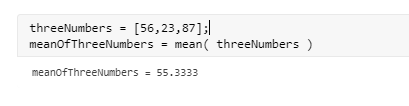

It is not necessary to display intermediate calculations.  If you wish you may also type your answer in the Text portion of the script.  

For example, type*** "The mean of the three numbers is 55.333".  ***Make it easy for me to find your answer to the problem!

If the answer to a problem is a graph be sure to include a descriptive title and label the X and Y axes!

When you have completed your exam export the Live script file to a PDF file.  

Export your Live Script File to a PDF by clicking the down arrow below the Save Icon and selecting Export to PDF.   Before submitting your file, open it and check that it rendered well, that all the graphs are properly displaying and that your text looks clear.

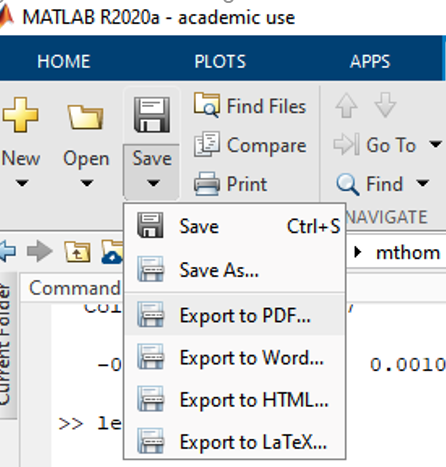

Submit your PDF and MLX file(s) to the Assignments Section of myCourses.  **DO NOT SUBMIT A ZIP FILE!  IF YOUR FILE IS NOT IN pdf FORMAT IT WILL NOT BE GRADED!**

I will be on-line during the exam  time from 8:00AM to 10:30AM on 12/12. Links to ZOOM have been posted in the myCourses calendar and shown below

#### Topic: EEET.425.01 - Digital Signal Processing Final Exam

#### Time: Dec 12, 2024 08:00 AM Eastern Time (US and Canada)

#### Join Zoom Meeting

#### [https://rit.zoom.us/j/95298558481?pwd=Fvz2uaXCNqhJsbLUENmqdVcAKZVNWI.1](https://rit.zoom.us/j/95298558481?pwd=Fvz2uaXCNqhJsbLUENmqdVcAKZVNWI.1)

#### Meeting ID: 952 9855 8481

#### Passcode: dspclass

# Problem 1 (20 Points)

#### Signal to Noise ratio, MAV Filters, Convolution

#### You have been tasked by your boss to analyze a signal. The signal is from a pressure sensor whose output is primarily DC, but it is corrupted with some noise from a noisy power supply and nearby machinery.  It is being sampled at a rate of 22 kHz.  The signal is contained in the MATLAB file "P1_Pressure_Sensor_Data.mat".  You can find the file on myCourses.  Follow the steps below to perform the analysis.

#### Download the file "P1_Pressure_Sensor_Data.mat" from myCourses.  Put it into your working directory where you can access the file.

#### A)  Load the file "P1_Pressure_Sensor_Data.mat".  The file contains a variable named "pressureData".  The first column is the sample number and the second colum is the signal data.  Plot the data versus the sample number

%
%  Put your MATLAB solution here
%
filename = "P1_Pressure_Sensor_Data.mat";
load(filename);

sampleNum = pressureData(:,1);
signalData = pressureData(:,2);


#### B)  Using MATLAB compute the mean and the standard deviation of the data of the input signal

% Compute the mean and standard deviation

%
%  Put your MATLAB solution here
%

meanInput = mean(signalData)

meanInput = 11.8028

stdInput = std(signalData)

stdInput = 6.9513

#### C)  Compute the signal to noise ratio of the input signal in decibels

%
%  Put your MATLAB solution here
%

snrInput = 20*log10(meanInput/stdInput)

snrInput = 4.5984

#### D) Your boss wants you to remove some of the noise to improve the signal to noise ratio.  You decide to use a Moving Average Filter with a kernel length of 8 to reduce some of the noise.

#### What is the impulse response of a moving average filter of length 8?  Create a variable with that impulse response. Use the syntax hMAV  = [ a,b,c,.... ]  replacing the variables a,b,c  with the values of your impulse response.  Make sure that your MAV filter has a DC gain of 1.0. 

%
%  Put your MATLAB solution here
%

N = 8;  % kernel length of 8
hMAV = ones(1,N) / N  % MAV impulse response with DC gain of 1.0 (each value is 1/N)

hMAV =     0.1250    0.1250    0.1250    0.1250    0.1250    0.1250    0.1250    0.1250


#### E)  Compute the frequency response of the MAV filter using 512 points.  Plot the magnitude of the frequency response versus the absolute frequency using a linear vertical scale.  Recall that the sample rate is 22 kHz.

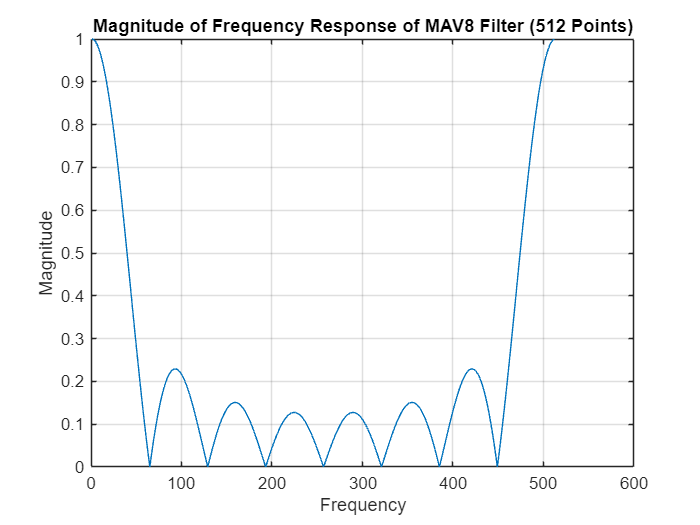

%  Compute the frequency response of the MAV filter using 512 points.  Plot
%  the magnitude of the response vs. absolute frequency.
%
%  Put your MATLAB solution here
%

% find frequency response of MAV filter using 512 points
hMAVfreq = fft(hMAV, 512);

% plot the magnitude of the response
figure
plot(abs(hMAVfreq))
grid 'on'
xlabel('Frequency')
ylabel('Magnitude')
title('Magnitude of Frequency Response of MAV8 Filter (512 Points)')

#### F)  Convolve the input signal with the MAV filter impulse response.  Use time domain convolution and the appropriate MATLAB function to do this.  Determine the length of the end effects and remove the end effects from the resulting signal.  Plot the result of the filtering operation with the end effects removed.

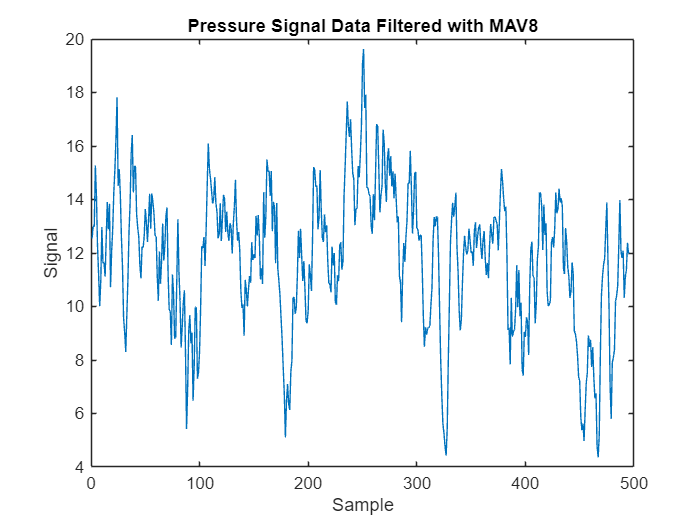

%
%  Put your MATLAB solution here
%

% perform time-domain convolution
out1 = conv(signalData, hMAV);

% end effects are equivalent to the length of the impulse response on both ends
convResult = out1(N:length(out1) - N);

figure
grid 'on'
plot(convResult)
xlabel('Sample')
ylabel('Signal')
title('Pressure Signal Data Filtered with MAV8')

#### G)  Using MATLAB compute the mean and standard deviation of the output of the filter

%  Compute the mean and standard deviation of the filter output
%
%  Put your MATLAB solution here
%

meanOutput = mean(convResult)

meanOutput = 11.8120

stdOutput = std(convResult)

stdOutput = 2.6013

#### H)  Compute the SNR of the filter output in decibels

%  Compute the SNR of the filter output in decibels
%
%  Put your MATLAB solution here
%

snrOutput = 20*log10(meanOutput/stdOutput)

snrOutput = 13.1428

#### I)  Describe the difference (if any) between the input signal SNR and the SNR of the signal at the output of the filter.  If there is a difference why is there a difference?

There is a significant difference between the input SNR and the SNR of the filter output. The application of the filter leads to a huge drop in signal noise, which in turn increases the signal SNR.

# Problem 2  FIR Filters and Linear Systems (20 Points)

#### Two filter impulse responses are saved in the MATLAB file 'P2_Filter_Impulse_Responses.mat'.  Load the file.  This will load two variables into the workspace.  IR_A and IR_B for impulse response A and impulse response B.  The sampling rate for each impulse response is 10 kHz.

#### A)  Load the MATLAB data file 'P2_Filter_Impulse_Responses.mat' and plot the impulse response IR_A.  

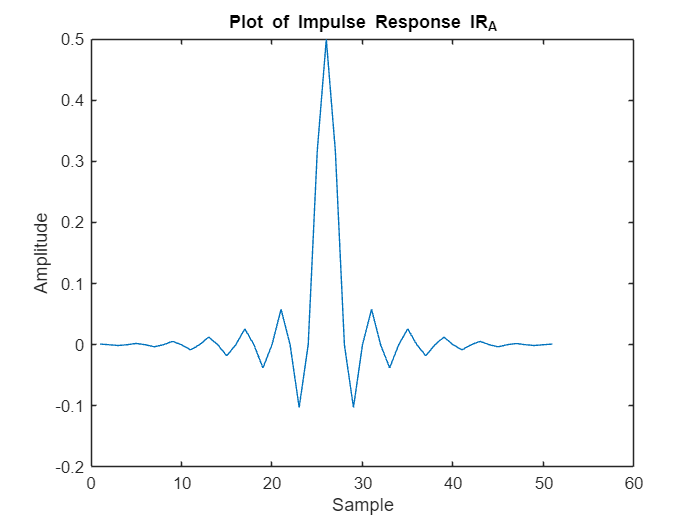

%  Load the file and plot the impulse response IR_A
%
%  Put your MATLAB solution here
%
clear
filename = 'P2_Filter_Impulse_Responses.mat';
load(filename)

figure
plot(IR_A)
xlabel('Sample')
ylabel('Amplitude')
title('Plot of Impulse Response IR_A')

#### B)  Compute the frequency response of IR_A using the correct number of points such that the frequency resolution is at least 10 Hz and the number of points is a power of 2.  Plot the frequency response versus the absolute frequency from 0 to the Nyquist frequency.  Recall that the sample rate is 10 kHz

%  Plot the frequency response of IR_A
%
%  Put your MATLAB solution here
%

% want frequency resolution to be at least 10Hz and sampling at 10kHz
fres = 10;
sampleRate = 10*10^3;
numSamples = sampleRate / fres;

% find nearest power of 2
pow2 = ceil(log2(numSamples));
numPoints = 2^pow2

numPoints = 1024

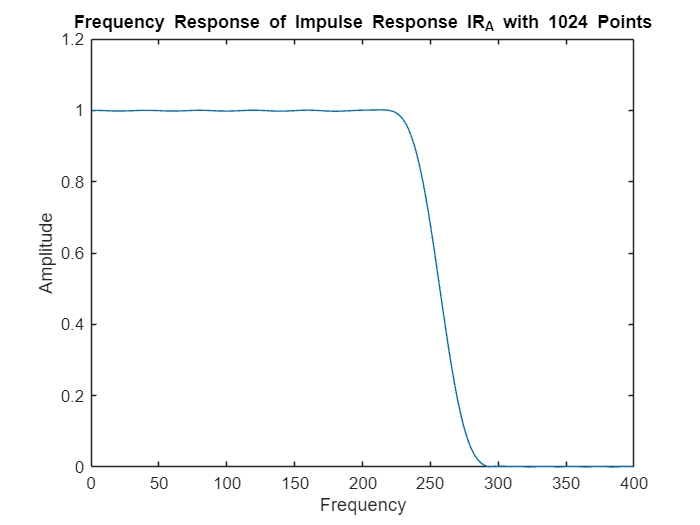


fftA = fft(IR_A,numPoints);

figure
grid 'on'
plot(abs(fftA))
xlim([0 400])
xlabel('Frequency')
ylabel('Amplitude')
title('Frequency Response of Impulse Response IR_A with 1024 Points')

#### C)  Plot the impulse response IR_B

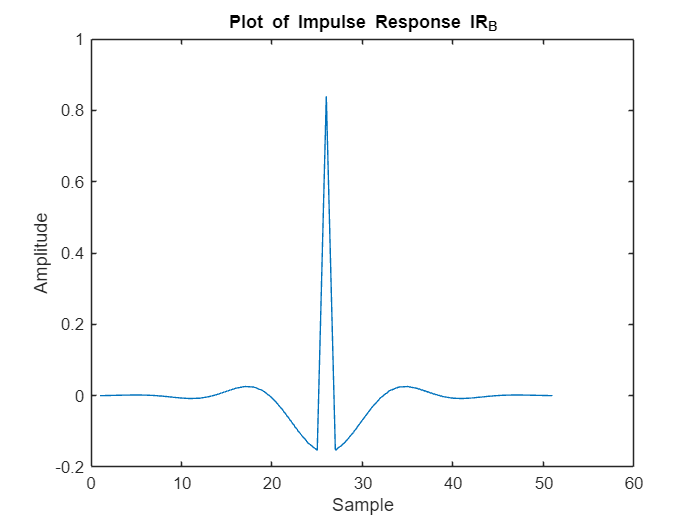

% Plot the impulse response IR_B
%
%  Put your MATLAB solution here
%

figure
plot(IR_B)
xlabel('Sample')
ylabel('Amplitude')
title('Plot of Impulse Response IR_B')

#### D)  Compute the frequency response of IR_B using the correct number of points such that the frequency resolution is at least 10 Hz and the number of points is a integer power of 2 (e.g. 2^7).  Plot the frequency response versus the absolute frequency from 0 to the Nyquist frequency.

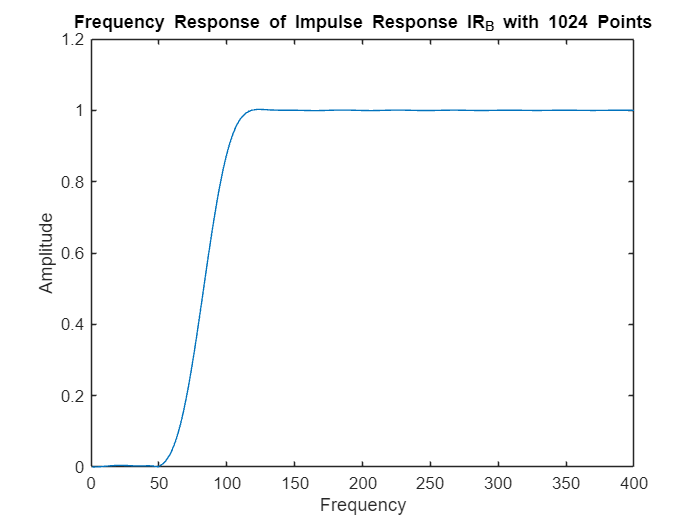

%  Plot the frequency response of IR_B
%
%  Put your MATLAB solution here
%

fftB = fft(IR_B,numPoints);

figure
grid 'on'
plot(abs(fftB))
xlim([0 400])
xlabel('Frequency')
ylabel('Amplitude')
title('Frequency Response of Impulse Response IR_B with 1024 Points')

#### E) If the two impulse responses are combined in series as shown in the diagram below, describe what type of filter will result?

IR_A is the impulse response of a low-pass filter, while IR_B is the impulse response of a high-pass filter. When combined in series, they should create a band-pass filter.

#### F)  Combine the two impulse responses in series.  Compute the frequency response of the combined impulse responses to the same resolution as in parts B and D.  Plot the frequency response versus the absolute frequency from 0 to the Nyquist frequency

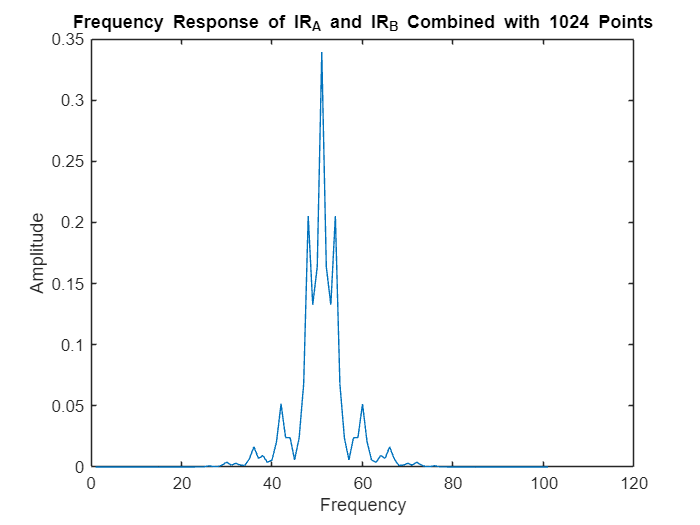

%  Combine the two impulse resonses, find the frequency response and plot
%  it
%
%  Put your MATLAB solution here
%

% when cascading impulse responses, perform convolution
combined = conv(IR_A, IR_B);

% find frequency response to same number of points
fftCombined = fft(combined, numPoints);

% plot the combined impulse responses
figure
grid 'on'
plot(abs(combined))
xlabel('Frequency')
ylabel('Amplitude')
title('Frequency Response of IR_A and IR_B Combined with 1024 Points')

# Problem 3 (20 Points)

## Dither, Oversampling and Averaging, Quantization noise

#### The signal to noise ratio (in decibels) of an audio input as measured by the ratio of standard deviations is 14 dB.  The signal level measured by its standard deviation $\sigma_S
$ is 15 mV. The input signal is being sampled by an 10-bit ADC convertor with a full scale voltage of 8V (0V to 8V).  Dither noise with a standard deviation $\sigma_D
$ of 18 mV is being added to the input prior to conversion to a digital signal. See the figure below describing the system.

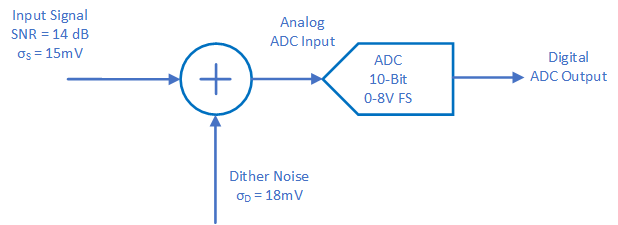

#### A)  What is the SNR of the input signal expressed as a numerical ratio?

%
%  Put your MATLAB solution here
%
clear

snrNum = 10^(14/10)

snrNum = 25.1189

#### B)  What is the standard deviation of the noise on the input signal?   Use correct units.

%  Put your MATLAB solution here

% noise is standard deviation?
noiseInput = 0.015

noiseInput = 0.0150


% but just in case there's this too
stdInput = std(noiseInput)

stdInput = 0

#### C)  What is the value of one code level of the ADC?

% Put your MATLAB solution here

n = 10;  % number of bits
fsv = 8;  % full-scale voltage
oneCV = fsv / (2^n - 1)

oneCV = 0.0078

#### D) What is the standard deviation of the quantization noise of the ADC?

%  Put your MATLAB solution here

noiseQuant = 0.29 * oneCV

noiseQuant = 0.0023

% again just in case
stdQuant = std(noiseQuant)

stdQuant = 0

#### E) What is the standard deviation of the total noise of the samples out of the ADC in terms of voltage?  Include input noise, dither noise  and quantization noise in your calculation.

%  Put your MATLAB solution here

noiseDither = 0.018;

noiseTotal = sqrt(noiseInput^2 + noiseDither^2 + noiseQuant^2)

noiseTotal = 0.0235

#### F) Oversampling and averaging is being used to reduce the output noise.  How many samples must be averaged to reduce the standard deviation of the total noise to a value no greater than 1 mV?

%  Put your MATLAB solution here

% want total noise to be no more than 1 mV
noiseAve = 0.001;

numSamples = ceil((noiseTotal / noiseAve)^2)

numSamples = 555

# Problem 4 (20 Points)

## Sampling and Aliasing

#### A signal consists of two sinewaves of 10 kHz and 23 kHz.  The signal is sampled at a rate of 30 kHz.

#### A)  After sampling what are the positive and negative frequency components falling in the Nyquist frequency range for -15 kHz to 15 kHz?

***For the 10kHz sinewave, no frequency components will fall within the range of -15kHx to 15kHz (positive components at 40kHz, -20kHz and negative components at 20kHz, 50kHz). For the 23kHz sinewave, the frequency components that will fall within the nyquuist frequency are as follows:***

    *23kHz - 30kHz =**** -7kHz***

    *-23kHz + 30kHz =**** 7kHz***

#### B)  Which frequencies within the Nyquist frequency range from -15 kHz to 15 kHz are a result of aliasing?

***Both 7kHz and -7kHz are the result of aliasing of the 23kHz signal.***

#### C)  Does this input signal meet the Nyquist criteria for sampling?  Why or why not?

***This input signal does not meet the Nyquist criteria for sampling. With a frequency component of 23kHz, the sampling frequency should be at least double which gives a minimum sampling frequency of 46kHz.***

# Problem 5 (20 Points)

## Project Questions -- Write a brief answer to each of the following questions

#### A)   What is the function of the equalizer in the project?

The function of the equalizer is to remove the temperature drift caused by the LM61 temperature sensor. It does this by compensating for the response of the LM61's leaky integrator.

#### B)  What is the purpose of performing dithering and oversampling and averaging on the incoming signal?

The purpose of performing the above three operations is to allow the ADC to create a more accurate representation of the analog signal. The addition of dither noise helps to avoid the quantization levels getting "stuck," while oversample averaging reduces the signal noise level.

#### C)  What is the purpose of using an interrupt timer in the system? 

The purpose of the interrupt timer is to sync the arduino sample rate to the timer rate so the arduino does not sample obscenely quickly.

#### D)  In your project how was the breathing rate determined?

The breathing rate was determined through a combination of low, high, and band-pass filters. The low-pass detected rates under 12 BPM, the high-pass detected rates above 40 BPM, and the band-pass detected rates in between the low and high.

#### E) In completing the final project, what was the biggest challenge you encountered?  How did you overcome it?

The biggest challenge we encountered was fine-tuning the warning logic but even that did not take us a large amount of time. I am super happy with how well our project went and with the group I worked with!